Нормированные сферические гармоники Yml(θ, φ) волновой функции ψnml(r, θ, φ) для квантовых s- и p-состояний водородоподобных атомов:

s: (m = 0, l = 0) Y(θ, φ) = sqrt(1/  4pi)

p: (m = 0, l = 1) Y(θ, φ) = sqrt(3 / pi) * cosθ / 2

(m = 1, l = 1) Y(θ, φ) = -sqrt(3 / 2pi) * sinθ * exp(iφ) / 2

clc, clear, close all
datetime('now')

ans = datetime
   05-May-2023 21:16:45


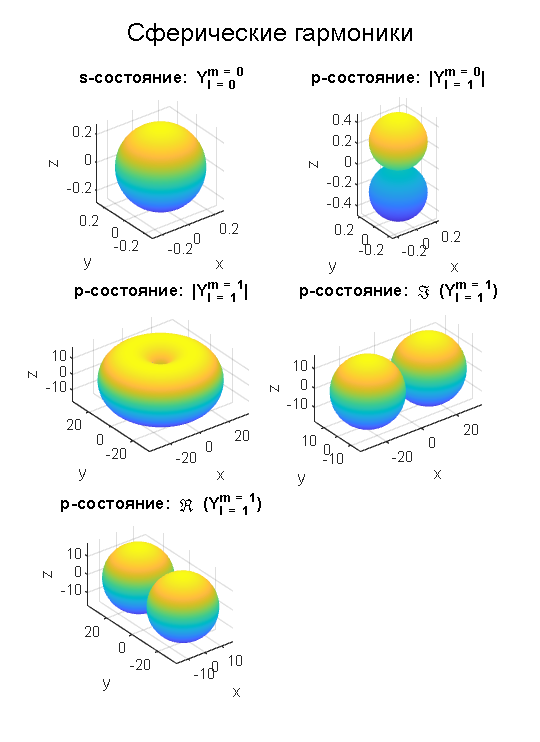


phi = linspace(0, 2 * pi);
theta = linspace(0, pi);
[phi, theta] = meshgrid(phi, theta);

F_1 = sqrt(1 / (4 * pi));
F_2 = 1 / 2 * sqrt(3 / pi) * cos(theta);
F_3 = -1 / 2 * sqrt(3 / (2 * pi)) * sin(theta) * exp(1i * phi);

set(gcf, 'Position',  [200, 60, 400, 550]);

subplot(3, 2, 1);
[x, y, z] = sph2cart(phi, pi / 2 - theta, F_1);
surf(x, y, z);
shading interp;
axis equal;
xlabel('x');
ylabel('y');
zlabel('z');
title ('s-состояние: Y_{l = 0}^{m = 0}');

subplot(3, 2, 2);
[x, y, z] = sph2cart(phi, pi / 2 - theta, abs(F_2));
surf(x, y, z);
shading interp;
axis equal;
xlabel('x');
ylabel('y');
zlabel('z');
title ('p-состояние: |Y_{l = 1}^{m = 0}|');

subplot(3, 2, 3);
[x, y, z] = sph2cart(phi, pi / 2 - theta, abs(F_3));
surf(x,y,z);
shading interp;
axis equal;
xlabel('x');
ylabel('y');
zlabel('z');
title ('p-состояние: |Y_{l = 1}^{m = 1}|');

subplot(3, 2, 4)
[x, y, z] = sph2cart(phi, pi / 2 - theta, abs(real(F_3)));
surf(x, y, z);
shading interp;
axis equal;
xlabel('x');
ylabel('y');
zlabel('z');
title ('p-состояние: \Im (Y_{l = 1}^{m = 1})');

subplot(3, 2, 5);
[x, y, z] = sph2cart(phi, pi / 2 - theta, abs(imag(F_3)));
surf(x, y, z);
shading interp;
axis equal;
xlabel('x');
ylabel('y');
zlabel('z');
title ('p-состояние: \Re (Y_{l = 1}^{m = 1})');

sgtitle('Сферические гармоники');